eqa = importdata('..//..//temp//simu86400//eqa_86400.txt'); 
diff_eqa = diff(eqa, 1, 1); diff_diff_eqa = diff(diff_eqa, 1, 1); diff_diff_diff_eqa = diff(diff_diff_eqa, 1, 1); diff_diff_diff_diff_eqa = diff(diff_diff_diff_eqa, 1, 1);
eqb = importdata('..//..//temp//simu86400//eqb_86400.txt'); diff_eqb = diff(eqb);

pc_a = [1.50; 0.00004; 0.00004];
pc_b = [1.50; 0.00004; 0.00004];

t = 0: 5: 86400 - 5;
alt_angle_sin = deg2rad(2 + 1 * sin(2 * pi / 250 * t))';
phase_centre_simu = pc_a(1) + pc_b(1) * cos(alt_angle_sin) - pc_b(3) * sin(alt_angle_sin); diff_simu = diff(phase_centre_simu); diff_diff_simu = diff(diff_simu); diff_diff_diff_simu = diff(diff_diff_simu); diff_diff_diff_diff_simu = diff(diff_diff_diff_simu);
phase_centre_simu = importdata('../../temp/simu86400/simu_86400.txt'); diff_simu = diff(phase_centre_simu); diff_diff_simu = diff(diff_simu);
% phase_centre_simu = eqa(:, 1: 3) * pc_b + eqa(:, 4: 6) * pc_a; diff_simu = diff(phase_centre_simu);
diff_eqb = diff_eqb + diff_simu;
diff_diff_eqb = diff(diff_eqb);
diff2_eqa = diff_diff_eqa; diff2_eqb = diff_diff_eqb;
diff3_eqb = diff(diff_diff_eqb); diff3_eqa = diff(diff_diff_eqa); diff3_simu = diff(diff_diff_simu);
diff4_eqb = diff(diff3_eqb); diff4_eqa = diff(diff3_eqa, 1, 1); diff4_simu = diff(diff3_simu);

start = 1;
len = 600;
end_s = len + start - 1;
eqa1 = filter_pdfree(Num, diff2_eqa(start: end_s, [1 3 2 4 5 6]));
eqa2 = filter_pdfree(Num, diff2_eqa(end_s * 1 + 1: end_s * 1 + len, :));
eqa3 = filter_pdfree(Num, diff2_eqa(end_s * 2 + 1: end_s * 2 + len, [4 5 6 1 3 2]));
eqa4 = filter_pdfree(Num, diff2_eqa(end_s * 3 + 1: end_s * 3 + len, [4 5 6 1 2 3]));
eqb1 = filter_pdfree(Num, diff2_eqb(start: end_s)) - eqa1(:, [1 4]) * [1.5; 1.5];
eqb2 = filter_pdfree(Num, diff2_eqb(end_s*1 + 1: end_s*1 + len)) - eqa2(:, [1 4]) * [1.5; 1.5];
eqb3 = filter_pdfree(Num, diff2_eqb(end_s*2 + 1: end_s*2 + len)) - eqa3(:, [1 4]) * [1.5; 1.5];
eqb4 = filter_pdfree(Num, diff2_eqb(end_s*3 + 1: end_s*3 + len)) - eqa4(:, [1 4]) * [1.5; 1.5];
eqa_all = [eqa1; eqa2; eqa3; eqa4];
eqb_all = [eqb1; eqb2; eqb3; eqb4];
eqa_normal = eqa1(:, [2 3 5 6])' * eqa1(:, [2 3 5 6]) + eqa2(:, [2 3 5 6])' * eqa2(:, [2 3 5 6]) + eqa3(:, [2 3 5 6])' * eqa3(:, [2 3 5 6]) + eqa4(:, [2 3 5 6])' * eqa4(:, [2 3 5 6]);
eqb_normal = eqa1(:, [2 3 5 6])' * eqb1 + eqa2(:, [2 3 5 6])' * eqb2 + eqa3(:, [2 3 5 6])' * eqb3 + eqa4(:, [2 3 5 6])' * eqb4;

lsqr(eqa1, eqb1)

lsqr 在解的 迭代 5 处收敛，并且相对残差为 1。


ans =    -105.536932950479e-006
   -792.908400243756e-006
   -8.21259364818242e-003
    1.02585010482864e-006
    4.01243884557900e-003
    466.411707200107e-006


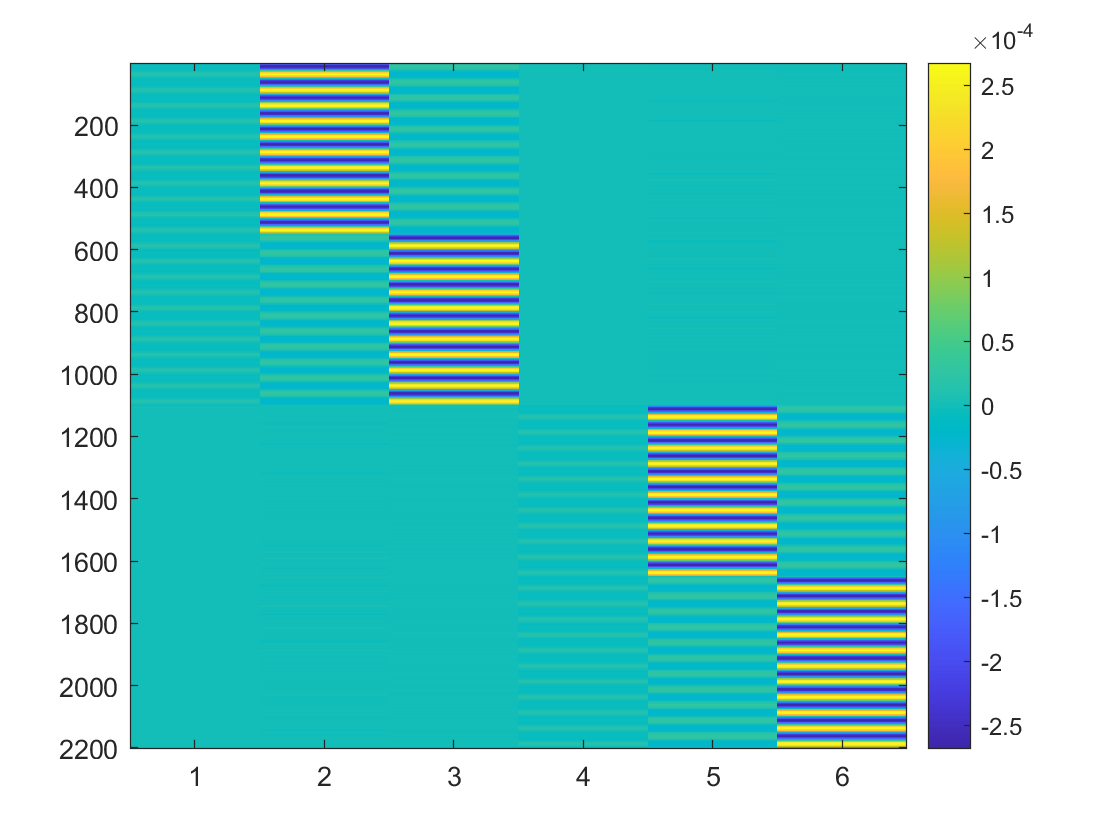


imagesc(eqa_all); colorbar

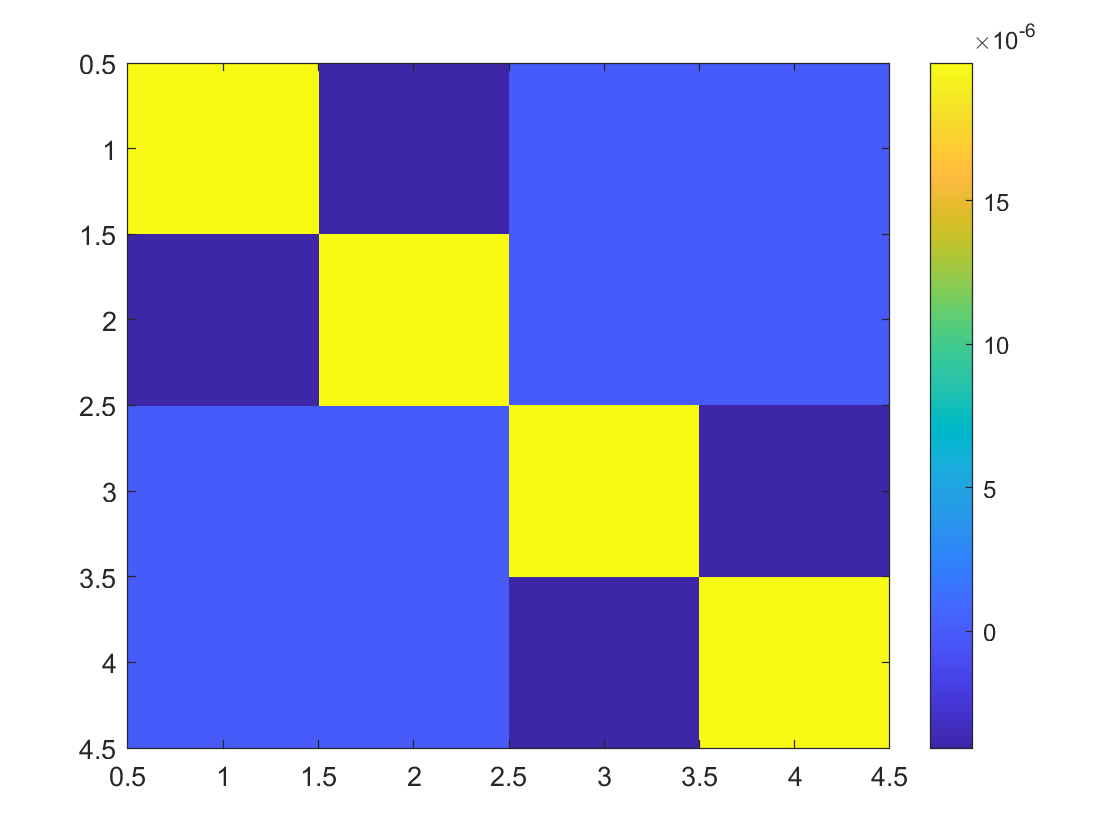

imagesc(eqa_normal); colorbar

cond(eqa_normal)

ans =     1.51633712564164e+000


bbbb = lsqr(eqa_normal, eqb_normal)

lsqr 在解的 迭代 4 处收敛，并且相对残差为 4.1e-19。


bbbb =     63.4660130596251e-006
    164.918179368999e-006
   -162.468468875178e-006
   -78.4508409493912e-006


acos(dot(bbbb(1: 3), pc_a) / (norm(bbbb(1: 3)) * norm(pc_a)))

ans =     1.30322327151524e+000


acos(dot(bbbb(4: 6), pc_b) / (norm(bbbb(4: 6)) * norm(pc_b)))

索引超出数组元素的数目(4)。

cccc = zeros(6, 1);
cccc([1 2]) = solver_spectral(eqa1, eqb1, [1 2], 0.2);
cccc([1 3]) = solver_spectral(eqa2, eqb2, [1 3], 0.2);
cccc([4 5]) = solver_spectral(eqa3, eqb3, [4 5], 0.2);
cccc([4 6]) = solver_spectral(eqa4, eqb4, [4 6], 0.2);
cccc
acos(dot(cccc(1: 3), pc_b) / (norm(cccc(1: 3)) * norm(pc_b)))
acos(dot(cccc(4: 6), pc_b) / (norm(cccc(4: 6)) * norm(pc_b)))